clear; close; clc;

## Initialization and Decaleration

D_duct = convlength(1.5, "in", "m") % duct diameter (m)

D_duct = 0.0381

L = .1 % length of cone (m)

L = 0.1000


theta = linspace(0,pi/2,100);

% Quick calculations
r_duct = D_duct/2;


% half cone ( where alititude lies on a side of the cone and intersects its base)
A_D = 1/2 * D_duct * (theta)

A_D =          0    0.0003    0.0006    0.0009    0.0012    0.0015    0.0018    0.0021    0.0024    0.0027    0.0030    0.0033    0.0036    0.0039    0.0042    0.0045    0.0048    0.0051    0.0054    0.0057    0.0060    0.0063    0.0066    0.0070    0.0073    0.0076    0.0079    0.0082    0.0085    0.0088    0.0091    0.0094    0.0097    0.0100    0.0103    0.0106    0.0109    0.0112    0.0115    0.0118    0.0121    0.0124    0.0127    0.0130    0.0133    0.0136    0.0139    0.0142    0.0145    0.0148


O_D = sqrt( (r_duct .* sin(theta)).^2 + (r_duct .* (1 + cos(theta))).^2 + L.^2 )

O_D =     0.1070    0.1070    0.1070    0.1070    0.1070    0.1070    0.1070    0.1070    0.1070    0.1070    0.1070    0.1070    0.1070    0.1069    0.1069    0.1069    0.1069    0.1069    0.1069    0.1069    0.1068    0.1068    0.1068    0.1068    0.1068    0.1067    0.1067    0.1067    0.1067    0.1067    0.1066    0.1066    0.1066    0.1066    0.1065    0.1065    0.1065    0.1064    0.1064    0.1064    0.1063    0.1063    0.1063    0.1063    0.1062    0.1062    0.1061    0.1061    0.1061    0.1060


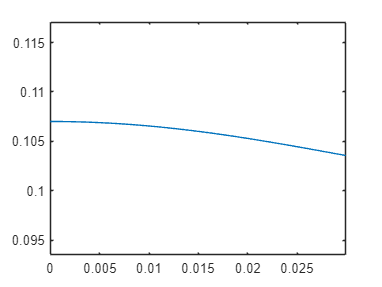

plot(A_D, O_D)
axis equal


% straight sides
E_G = -.005; % distance from horizontal line to surface of the missile
% todo: replace the -.5 with the analitical distance based on missile body radius
E_F = linspace(E_G, r_duct, 100); % distance away from horizontal line 
O_F = sqrt(r_duct.^2 + E_F.^2 + L.^2);

% these plots are wrong becuase they are plotting radius against arc length

C_F = -(E_F-max(E_F)) + max(A_D)

C_F =     0.0540    0.0537    0.0535    0.0532    0.0530    0.0528    0.0525    0.0523    0.0520    0.0518    0.0515    0.0513    0.0511    0.0508    0.0506    0.0503    0.0501    0.0498    0.0496    0.0494    0.0491    0.0489    0.0486    0.0484    0.0481    0.0479    0.0477    0.0474    0.0472    0.0469    0.0467    0.0464    0.0462    0.0460    0.0457    0.0455    0.0452    0.0450    0.0447    0.0445    0.0443    0.0440    0.0438    0.0435    0.0433    0.0430    0.0428    0.0426    0.0423    0.0421


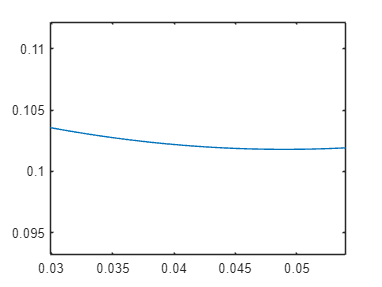

plot(C_F,O_F)
axis equal

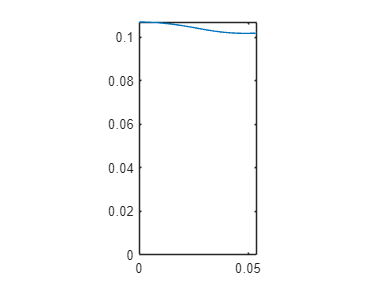


plot([A_D, fliplr(C_F)], [O_D, fliplr(O_F)])
axis equal
ylim([0,max(O_D)])
xlim([0,max(C_F)])

% print settinggs
% units: cm
% height: 13.76
% width: 12.32

plot([A_D, fliplr(C_F)], [O_D, fliplr(O_F)])
axis equal
ylim([0,max(O_D)])
xlim([0,max(C_F)])


figure;
% here is how to convert the semiconical section to xy coordinates
A_O = max(O_D);
y_semicone = 1/2 * (A_O - (A_D.^2 - O_D.^2) ./ A_O);
x_semicone = sqrt(-y_semicone.^2 + O_D.^2); % keeping the positive values of the root
% note that the imaginary component of x_semicone doesnt exist and only
% arrises due to numerical error at zero deflection
x_semicone = real(x_semicone);

% plot the net of the semicone
plot(x_semicone, y_semicone)
axis equal
ylim([0,max(y_semicone)])
xlim([0,max(C_F)])

% compute the points for the the straight edges
y_c = y_semicone(end)

y_c = 0.0994

x_c = x_semicone(end)

x_c = 0.0289

% convert E_F to C_F
E_C = r_duct % distance from halfway point of duct (max width) to base of duct (m)

E_C = 0.0190

C_F = -E_F + E_C

C_F =     0.0240    0.0238    0.0236    0.0233    0.0231    0.0228    0.0226    0.0223    0.0221    0.0219    0.0216    0.0214    0.0211    0.0209    0.0206    0.0204    0.0202    0.0199    0.0197    0.0194    0.0192    0.0189    0.0187    0.0185    0.0182    0.0180    0.0177    0.0175    0.0172    0.0170    0.0168    0.0165    0.0163    0.0160    0.0158    0.0155    0.0153    0.0151    0.0148    0.0146    0.0143    0.0141    0.0138    0.0136    0.0134    0.0131    0.0129    0.0126    0.0124    0.0121


r_c = C_F % distance from point c to current point (m)

r_c =     0.0240    0.0238    0.0236    0.0233    0.0231    0.0228    0.0226    0.0223    0.0221    0.0219    0.0216    0.0214    0.0211    0.0209    0.0206    0.0204    0.0202    0.0199    0.0197    0.0194    0.0192    0.0189    0.0187    0.0185    0.0182    0.0180    0.0177    0.0175    0.0172    0.0170    0.0168    0.0165    0.0163    0.0160    0.0158    0.0155    0.0153    0.0151    0.0148    0.0146    0.0143    0.0141    0.0138    0.0136    0.0134    0.0131    0.0129    0.0126    0.0124    0.0121


r_o = O_F % distance form origin to current point (m)

r_o =     0.1019    0.1019    0.1019    0.1019    0.1019    0.1019    0.1019    0.1019    0.1018    0.1018    0.1018    0.1018    0.1018    0.1018    0.1018    0.1018    0.1018    0.1018    0.1018    0.1018    0.1018    0.1018    0.1018    0.1018    0.1018    0.1018    0.1018    0.1018    0.1018    0.1018    0.1018    0.1018    0.1018    0.1018    0.1019    0.1019    0.1019    0.1019    0.1019    0.1019    0.1019    0.1019    0.1019    0.1019    0.1020    0.1020    0.1020    0.1020    0.1020    0.1020


% keepin just the positive solution for now
% these are the two sides of the root
%y = (x_c.*((- r_c.^2 + 2.*r_c.*r_o - r_o.^2 + x_c.^2 + y_c.^2).*(r_c.^2 + 2.*r_c.*r_o + r_o.^2 - x_c.^2 - y_c.^2)).^(1/2) - r_c.^2.*y_c + r_o.^2.*y_c + x_c.^2.*y_c + y_c.^3)./(2.*(x_c.^2 + y_c.^2))
% the second of the two y values works for the right hand side of the duct
y_side = (r_o.^2.*y_c - r_c.^2.*y_c - x_c.*((- r_c.^2 + 2.*r_c.*r_o - r_o.^2 + x_c.^2 + y_c.^2).*(r_c.^2 + 2.*r_c.*r_o + r_o.^2 - x_c.^2 - y_c.^2)).^(1/2) + x_c.^2.*y_c + y_c.^3)./(2.*(x_c.^2 + y_c.^2))

y_side =     0.0886    0.0887    0.0888    0.0889    0.0890    0.0891    0.0892    0.0893    0.0895    0.0896    0.0897    0.0898    0.0899    0.0900    0.0901    0.0902    0.0903    0.0904    0.0906    0.0907    0.0908    0.0909    0.0910    0.0911    0.0912    0.0913    0.0914    0.0915    0.0917    0.0918    0.0919    0.0920    0.0921    0.0922    0.0923    0.0924    0.0925    0.0926    0.0927    0.0929    0.0930    0.0931    0.0932    0.0933    0.0934    0.0935    0.0936    0.0937    0.0938    0.0940


x_side = 1./x_c * (1/2 .* (r_o.^2 - r_c.^2 + x_c.^2 + y_c.^2) - y_side .* y_c)

x_side =     0.0504    0.0502    0.0500    0.0498    0.0495    0.0493    0.0491    0.0489    0.0487    0.0485    0.0482    0.0480    0.0478    0.0476    0.0474    0.0472    0.0469    0.0467    0.0465    0.0463    0.0461    0.0459    0.0456    0.0454    0.0452    0.0450    0.0448    0.0446    0.0443    0.0441    0.0439    0.0437    0.0435    0.0433    0.0430    0.0428    0.0426    0.0424    0.0422    0.0420    0.0417    0.0415    0.0413    0.0411    0.0409    0.0407    0.0404    0.0402    0.0400    0.0398


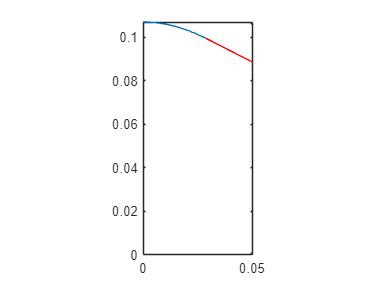

xlim([0,max(x_side)])

hold on
plot(x_side,y_side,"-r")

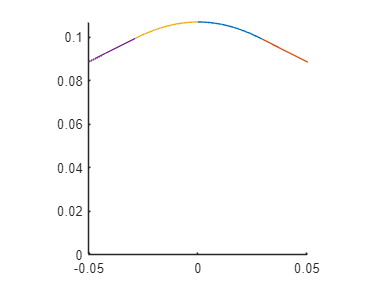

% print settinggs
% units: cm
% height: 14.80 cm
% width: 13.25 cm

figure;

% compute and plot full duct now
hold on;
%plot the positive side
plot(x_semicone,y_semicone)
plot(x_side,y_side)
%plot the negative side
plot(-x_semicone,y_semicone)
plot(-x_side,y_side)
%axis tight
axis equal
xlim([-max(x_side),max(x_side)])
ylim([0,max(y_semicone)])

% print settinggs
% units: cm
% height: 17.52 cm
% width: 13.07 cm